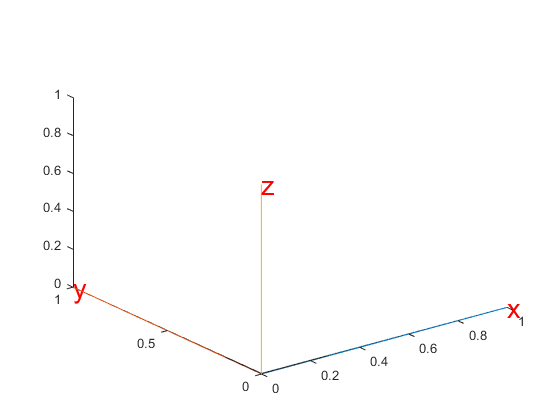

euler_deg=[90,0,0];%ZYX
euler_rad=degtorad(euler_deg);
x_axis=[1,0,0]';y_axis=[0,1,0]';z_axis=[0,0,1]';
plotAxis(x_axis,y_axis,z_axis)

p=[1,-1,0]';
% R=makehgtform('yrotate',euler_rad(1))*makehgtform('zrotate',euler_rad(1));
R=makehgtform('zrotate',euler_rad(1))*makehgtform('yrotate',euler_rad(1))

R =      0    -1     0     0
     0     0     1     0
    -1     0     0     0
     0     0     0     1


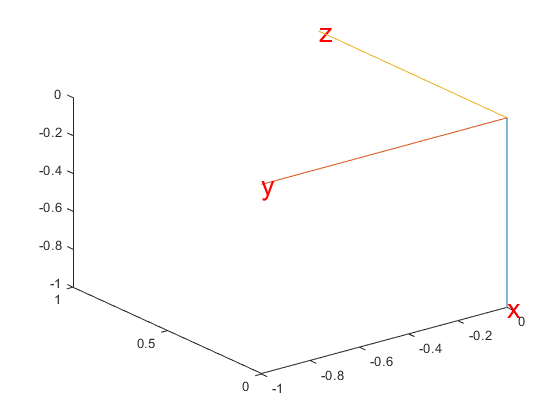

rotateP(R,p);
plotAxis(rotateP(R,x_axis),rotateP(R,y_axis),rotateP(R,z_axis))

function [none]=plotAxis(x_axis,y_axis,z_axis)

line3(x_axis);hold on;
line3(y_axis);
line3(z_axis);hold off
text(x_axis(1),x_axis(2),x_axis(3),'x','Color','red','FontSize',20)
text(y_axis(1),y_axis(2),y_axis(3),'y','Color','red','FontSize',20)
text(z_axis(1),z_axis(2),z_axis(3),'z','Color','red','FontSize',20)

end

function [p]=rotateP(R,p)

R=R(1:3,1:3);
p=R*p;

end